% DD_FORWARD_KINEMATICS_COMPARISON
% Compare standard DD kinematics vs coupled kinematics mapping.

clc; clear; close all;

%% Load physical parameters (expects phys.r, phys.L, phys.d)
[phys, ~] = mm_params_build_save_load('load', 'mm_params');

Loaded: mm_params.mat


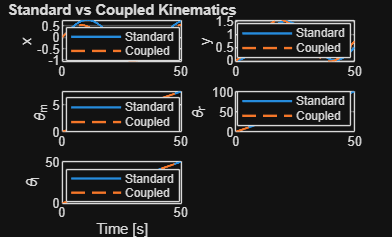

r = phys.r;
L = phys.L;
d = phys.d;

%% Time span and initial state
tspan = linspace(0, 50, 2001);         % fixed grid -> identical t for both models
X0    = [0; 0; 0; 0; 0];               % [x; y; theta_m; theta_r; theta_l]

%% Wheel angular velocity inputs (rad/s)
theta_r_dot_fun = @(t) 2.0;            % constant >0
theta_l_dot_fun = @(t) 1.0;            % constant >0

%% Simulate: standard model (no coupling)
odefun_dd = @(t,X) mobile_kinematics_dd( ...
    t, X, theta_r_dot_fun, theta_l_dot_fun, r, L);

[t, X_dd] = ode45(odefun_dd, tspan, X0);

%% Simulate: coupled model (with offset d)
odefun_cpl = @(t,X) mobile_kinematics_dd_coupling( ...
    t, X, theta_r_dot_fun, theta_l_dot_fun, r, L, d);

[~, X_cpl] = ode45(odefun_cpl, tspan, X0);   % same tspan grid as above

%% === Plots: States vs time (overlay) ===
state_labels = {'x','y','\theta_m','\theta_r','\theta_l'};

figure('Name','States Comparison','NumberTitle','off');
for i = 1:5
    subplot(3,2,i)
    plot(t, X_dd(:,i), 'LineWidth', 1.4); hold on;
    plot(t, X_cpl(:,i), '--', 'LineWidth', 1.4);
    ylabel(state_labels{i});
    grid on;
    if i == 1
        title('Standard vs Coupled Kinematics');
    end
    if i == 5
        xlabel('Time [s]');
    end
    legend('Standard','Coupled','Location','best');
end

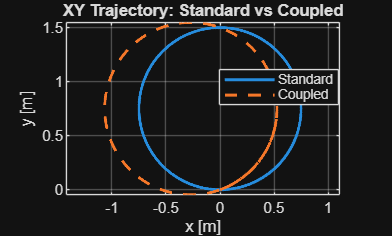


%% === Plots: XY trajectories (overlay) ===
figure('Name','Base Trajectory Comparison','NumberTitle','off');
plot(X_dd(:,1),  X_dd(:,2),  'LineWidth', 1.8); hold on;
plot(X_cpl(:,1), X_cpl(:,2), '--', 'LineWidth', 1.8);
xlabel('x [m]'); ylabel('y [m]');
axis equal; grid on;
legend('Standard','Coupled','Location','best');
title('XY Trajectory: Standard vs Coupled');

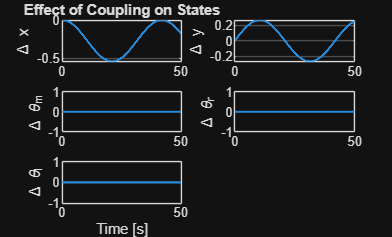


%% === Plots: State Differences (Coupled - Standard) ===
dX = X_cpl - X_dd;

figure('Name','State Differences (Coupled - Standard)','NumberTitle','off');
for i = 1:5
    subplot(3,2,i)
    plot(t, dX(:,i), 'LineWidth', 1.4);
    ylabel(['\Delta ', state_labels{i}]);
    grid on;
    if i == 1
        title('Effect of Coupling on States');
    end
    if i == 5
        xlabel('Time [s]');
    end
end


%% ===== Local functions =====

function dX = mobile_kinematics_dd(t, X, theta_r_dot_fun, theta_l_dot_fun, r, L)
    theta_m = X(3);
    u = [theta_r_dot_fun(t); theta_l_dot_fun(t)];
    R = R_dd(theta_m, r, L);
    dX = R * u;
end

function dX = mobile_kinematics_dd_coupling(t, X, theta_r_dot_fun, theta_l_dot_fun, r, L, d)
    theta_m = X(3);
    u = [theta_r_dot_fun(t); theta_l_dot_fun(t)];
    R = R_dd_coupling(theta_m, r, L, d);
    dX = R * u;
end

function R = R_dd(theta_m, r, L)
    % Standard DD mapping at chassis center.
    %
    % q = [x; y; theta_m; theta_r; theta_l]
    % u = [theta_r_dot; theta_l_dot]
    cm = cos(theta_m);
    sm = sin(theta_m);
    R = [ ...
        (r/2)*cm,   (r/2)*cm;      % x_dot
        (r/2)*sm,   (r/2)*sm;      % y_dot
         r/(2*L),  -r/(2*L);       % theta_m_dot
         1,         0;             % theta_r_dot
         0,         1              % theta_l_dot
    ];
end

function R = R_dd_coupling(theta_m, r, L, d)
    % Coupled mapping for mobile base + offset point (e.g. manipulator base).
    %
    % q = [x; y; theta_m; theta_r; theta_l]
    % u = [theta_r_dot; theta_l_dot]
    %
    % First two rows are velocity of the offset point including the effect of d.
    cm = cos(theta_m);
    sm = sin(theta_m);
    R = [ ...
        (r/(2*L))*(L*cm - d*sm),  (r/(2*L))*(L*cm + d*sm);  % x_dot (offset frame)
        (r/(2*L))*(L*sm + d*cm),  (r/(2*L))*(L*sm - d*cm);  % y_dot (offset frame)
         r/(2*L),                -r/(2*L);                  % theta_m_dot
         1,                       0;                        % theta_r_dot
         0,                       1                         % theta_l_dot
    ];
end
